%% initialize environments
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "vaiueo2d.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path);
audio_file_manipulator.load_properties();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : vaiueo2d.wav
output_file_path : default.wav
signal shape : (17500, 1)
sample_rate: 22050 [Hz]
             Filename: 'D:\名城大学\研究室\演習\MatlabPractice\SourceCode\Analysis\STRAIGHT\STRAIGHTV40_007b\vaiueo2d.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 22050
         TotalSamples: 17500
             Duration: 0.7937
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16

--------------------------------------------



%% set Cepstrum class parameters
start_point = 3748;  % あのスタート位置
continue_time = 32; % [ms]
continue_point = int32(continue_time * audio_file_manipulator.information.SampleRate / 1000);

%% generate Cepstrum instance and confirm properties
cepstrum = Cepstrum(audio_file_manipulator.signal(start_point : start_point + continue_point - 1), audio_file_manipulator.information.SampleRate);
cepstrum.display_properties();

----------------------------------------------
------------------ Cepstrum ------------------
signal size : (706, 1)
sample_rate : 22050 [Hz]
fft_point : 2048
amplitude_spectrum size : (2048, 1)
liftering_order : 44
voicing_threshold : 0.010000
cepstrum size : (2048, 1)
basic_period : 0.008571 [s]
basic_frequency : 116.666667 [Hz]
linear amplituded spectral envelope shape : (2048, 1)
impulse response of cepstrum shape : (2048, 1)
repeat_number : 10
basic_period_gain : 1.000000
synthesized signal size : (2177, 1)
----------------------------------------------



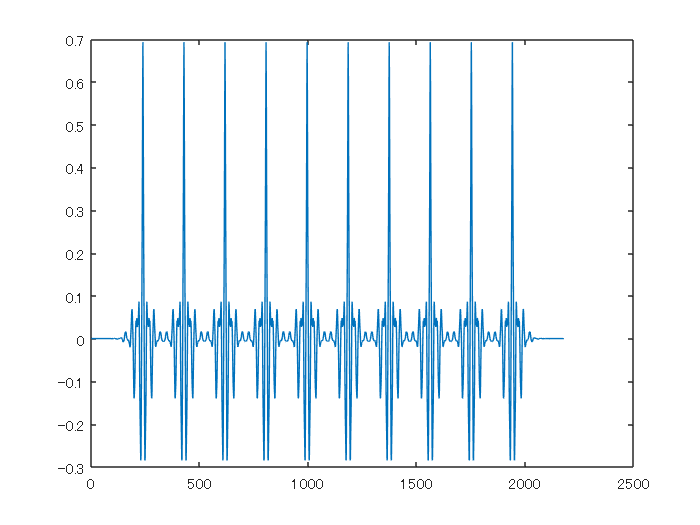

plot(cepstrum.synthesized_signal);